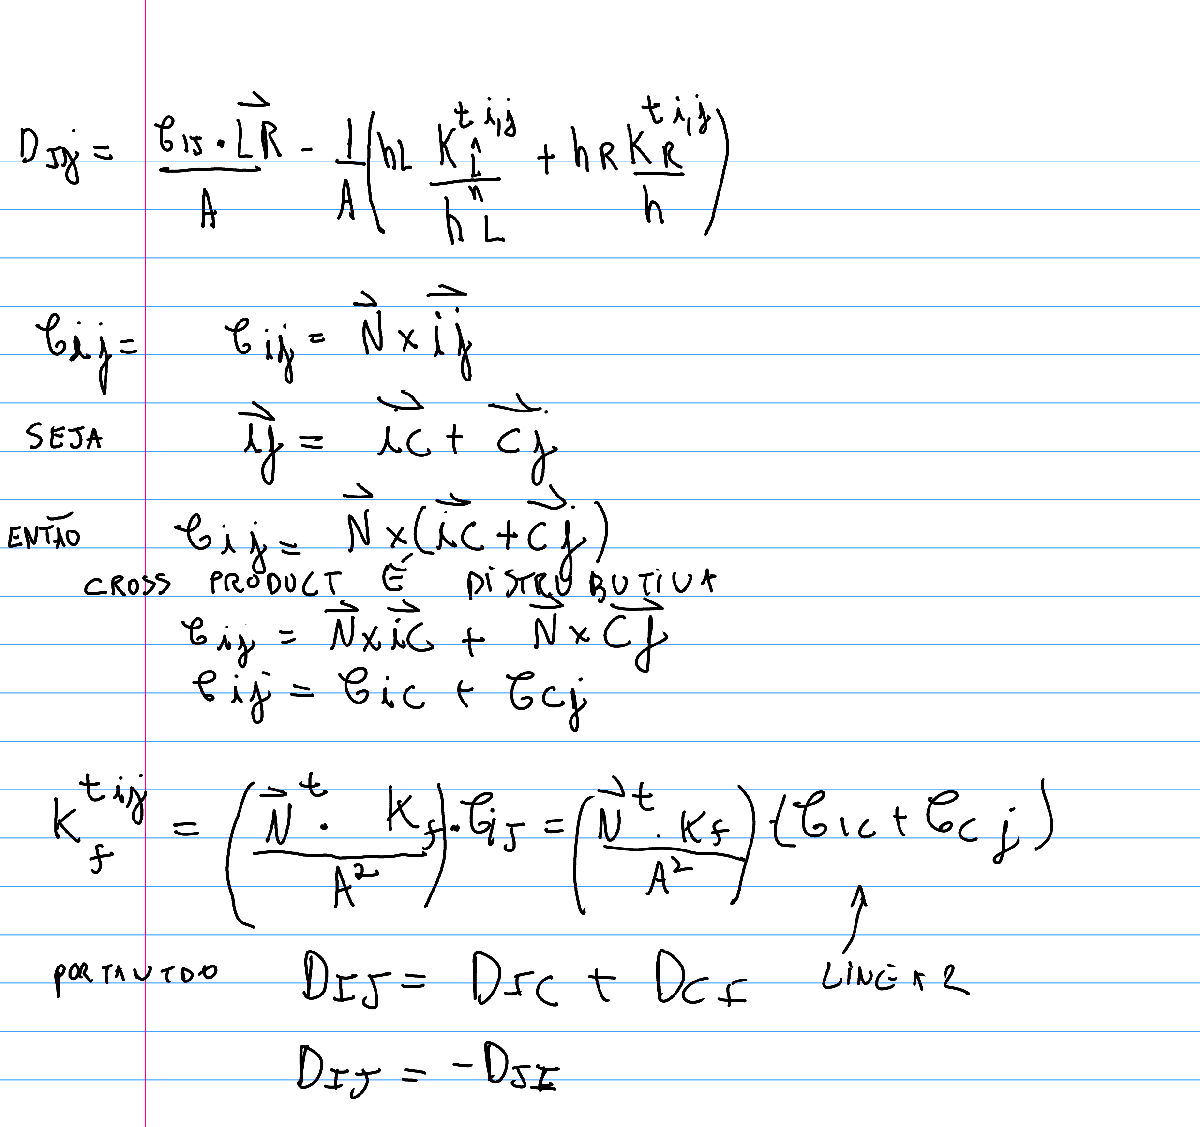

# **Total Flux Expression for a Tetrahedron**

#### **IJK**

syms K A u_r u_l  DJK DJI u_i u_j u_k 
F = ((u_r - u_l) - 0.5*DJK*(u_j - u_i) + 0.5*DJI*(u_j - u_k));
Fm = -K*A*collect(F,[u_r u_l u_i u_j u_k])

$$Fm = -A\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DJK}}{2}\,u_{i}+\left(\frac{\mathrm{DJI}}{2}-\frac{\mathrm{DJK}}{2}\right)\,u_{j}+\left(-\frac{\mathrm{DJI}}{2}\right)\,u_{k}\right)$$

Let a computational domain $\Omega$ be divided into distinct polyhedral cells $\Omega_k$, where the faces of these cells are triangular, quadrilateral, pentagonal, and hexahedrical. We present a generalization of the MPFA-D 3d method.

First, let us consider a quadrilateral face comprised by the nodes ABCD as described bellow.

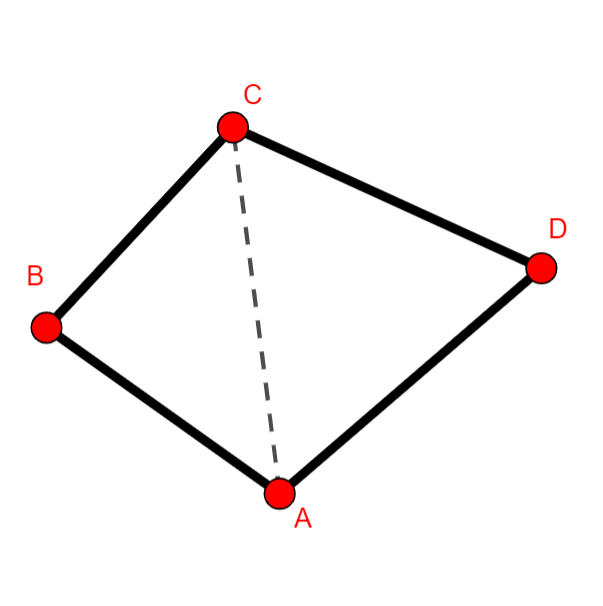

Without the loss of generalization, we can divide the quadrilateral in two trinagular faces ABC , and ACD and apply the original MPFA-D 3D flux expression on each on the triangle the the centers of the CVs to the left and to the right.

## Flux in ABC

**ABC**

syms u_a u_b u_c u_d DBC DBA A_1 u_r u_l
F_1 =  ((u_r - u_l) - 0.5*DBC*(u_b - u_a) + 0.5*DBA*(u_b - u_c));
F_ABC = -K*A_1*collect(F_1, [u_r u_l u_a u_b u_c])

$$F\_ABC = -A_{1}\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DBC}}{2}\,u_{a}+\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\,u_{b}+\left(-\frac{\mathrm{DBA}}{2}\right)\,u_{c}\right)$$

where $A_1$ is the Area of ABC.

## Flux in ACD

**ACD**

The process is repeated for the triangle ACD.

syms FJ u_a u_b u_c DCD DCA A_2
F_2 =  ((u_r - u_l) - 0.5*DCD*(u_c - u_a) + 0.5*DCA*(u_c - u_d));
F_ACD = -K*A_2*collect(F_2, [u_r u_l u_a u_c u_d])

$$F\_ACD = -A_{2}\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DCD}}{2}\,u_{a}+\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCA}}{2}\right)\,u_{d}\right)$$

## Resulting Flux 

**The resulting Flux is the sum of F_ABC, F_ACD;**

% [A_1*K A_2*K u_r u_l u_a u_b u_c u_d ]
F = collect(F_ABC + F_ACD, [A_1 A_2])

$$F = \left(-K\,\left(u_{r}-u_{l}+\frac{\mathrm{DBC}}{2}\,u_{a}+\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\,u_{b}+\left(-\frac{\mathrm{DBA}}{2}\right)\,u_{c}\right)\right)\,A_{1}+\left(-K\,\left(u_{r}-u_{l}+\frac{\mathrm{DCD}}{2}\,u_{a}+\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)\,u_{c}+\left(-\frac{\mathrm{DCA}}{2}\right)\,u_{d}\right)\right)\,A_{2}$$

We know that:

DBA = -DAB

DCA = - DAC = - DAB - DBC

syms DAB
Fn = subs(F,{DBA, DCA},{-DAB,  -DAB - DBC})

$$Fn = -A_{1}\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DAB}\,u_{c}}{2}+\frac{\mathrm{DBC}\,u_{a}}{2}-u_{b}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)\right)-A_{2}\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DCD}\,u_{a}}{2}-u_{c}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}+\frac{\mathrm{DCD}}{2}\right)+u_{d}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)\right)$$

Fm = collect(expand(Fn), [u_l u_r K])

$$Fm = \left(A_{1}+A_{2}\right)\,u_{l}\,K+\left(-A_{1}-A_{2}\right)\,u_{r}\,K+\left(\frac{A_{1}\,\mathrm{DAB}\,u_{b}}{2}-\frac{A_{1}\,\mathrm{DAB}\,u_{c}}{2}+\frac{A_{2}\,\mathrm{DAB}\,u_{c}}{2}-\frac{A_{2}\,\mathrm{DAB}\,u_{d}}{2}-\frac{A_{1}\,\mathrm{DBC}\,u_{a}}{2}+\frac{A_{1}\,\mathrm{DBC}\,u_{b}}{2}+\frac{A_{2}\,\mathrm{DBC}\,u_{c}}{2}-\frac{A_{2}\,\mathrm{DBC}\,u_{d}}{2}-\frac{A_{2}\,\mathrm{DCD}\,u_{a}}{2}+\frac{A_{2}\,\mathrm{DCD}\,u_{c}}{2}\right)\,K$$

Fn = collect(expand(subs(Fm, {A_1 + A_2}, {A})),[A*K u_l u_r u_a u_b u_c u_d ])

$$Fn = \begin{array}{l} \left(A\,K\right)\,u_{l}+\left(-A\,K\right)\,u_{r}+\left(-\sigma_{3}-\sigma_{1}\right)\,u_{a}+\left(\sigma_{5}+\sigma_{3}\right)\,u_{b}+\left(\sigma_{4}-\sigma_{5}+\sigma_{2}+\sigma_{1}\right)\,u_{c}+\left(-\sigma_{4}-\sigma_{2}\right)\,u_{d}\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{2}\,\mathrm{DCD}\,K}{2}\\ \sigma_{2}=\frac{A_{2}\,\mathrm{DBC}\,K}{2}\\ \sigma_{3}=\frac{A_{1}\,\mathrm{DBC}\,K}{2}\\ \sigma_{4}=\frac{A_{2}\,\mathrm{DAB}\,K}{2}\\ \sigma_{5}=\frac{A_{1}\,\mathrm{DAB}\,K}{2} \end{array}$$

For the sake of simplicity let us manipulate only the CDT.

Fcdt = Fn - A*K*u_l + A*K*u_r

$$Fcdt = u_{b}\,\left(\frac{A_{1}\,\mathrm{DAB}\,K}{2}+\frac{A_{1}\,\mathrm{DBC}\,K}{2}\right)-u_{d}\,\left(\frac{A_{2}\,\mathrm{DAB}\,K}{2}+\frac{A_{2}\,\mathrm{DBC}\,K}{2}\right)-u_{a}\,\left(\frac{A_{1}\,\mathrm{DBC}\,K}{2}+\frac{A_{2}\,\mathrm{DCD}\,K}{2}\right)+u_{c}\,\left(\frac{A_{2}\,\mathrm{DAB}\,K}{2}-\frac{A_{1}\,\mathrm{DAB}\,K}{2}+\frac{A_{2}\,\mathrm{DBC}\,K}{2}+\frac{A_{2}\,\mathrm{DCD}\,K}{2}\right)$$

Fcdt = collect(Fcdt, [u_a u_b u_c u_d A_1 A_2 K])

$$Fcdt = \left(-\frac{\mathrm{DBC}}{2}\right)\,u_{a}\,A_{1}\,K+\left(-\frac{\mathrm{DCD}}{2}\right)\,u_{a}\,A_{2}\,K+\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)\,u_{b}\,A_{1}\,K+\left(-\frac{\mathrm{DAB}}{2}\right)\,u_{c}\,A_{1}\,K+\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}+\frac{\mathrm{DCD}}{2}\right)\,u_{c}\,A_{2}\,K+\left(-\frac{\mathrm{DAB}}{2}-\frac{\mathrm{DBC}}{2}\right)\,u_{d}\,A_{2}\,K$$

AB + BC + CD + DA = 0, => AB + BC + CD = -DA 

Threfore, D(AB + BC  + CD) = - D(DA)

syms DDA

Fcdt = subs(collect(Fcdt,[DAB/2+ DBC/2 + DCD/2]), {DAB/2 + DBC/2 + DCD/2}, {-DDA/2})

$$Fcdt = A_{1}\,K\,u_{b}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)-A_{2}\,K\,u_{d}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)-\frac{A_{1}\,\mathrm{DAB}\,K\,u_{c}}{2}-\frac{A_{1}\,\mathrm{DBC}\,K\,u_{a}}{2}-\frac{A_{2}\,\mathrm{DCD}\,K\,u_{a}}{2}-\frac{A_{2}\,\mathrm{DDA}\,K\,u_{c}}{2}$$

Fcdt = collect(expand(2*Fcdt), [u_a u_b u_c u_d])/2

$$Fcdt = -\frac{u_{a}\,\left(A_{1}\,\mathrm{DBC}\,K+A_{2}\,\mathrm{DCD}\,K\right)}{2}+\frac{u_{b}\,\left(A_{1}\,\mathrm{DAB}\,K+A_{1}\,\mathrm{DBC}\,K\right)}{2}-\frac{u_{c}\,\left(A_{1}\,\mathrm{DAB}\,K+A_{2}\,\mathrm{DDA}\,K\right)}{2}-\frac{u_{d}\,\left(A_{2}\,\mathrm{DAB}\,K+A_{2}\,\mathrm{DBC}\,K\right)}{2}$$

## Flux Expression of a Pentagonal Face

To find the flux expression of the flux across a pentagonal face, we can repeat the same process. Let ABCDE be a pentagon face as despicted bellow:

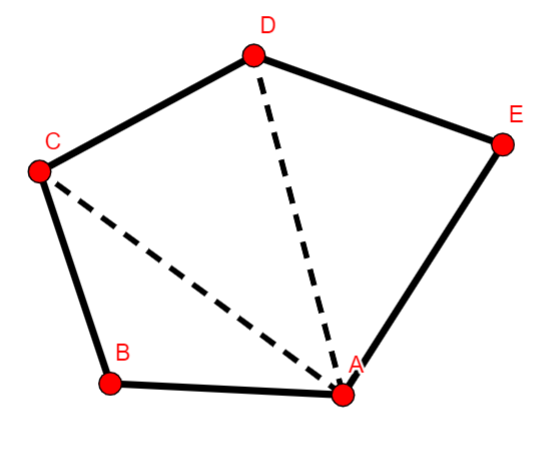

The tesselation above divides the control surface in 3 distinct triangular faces, ABC, ACD and ADE, with correspondign areas of A_1 A_2 A_3. This way, we can find the flux expression for this face by summing the flux expression for each triangle in the tessellation.  The expression for F_ABC and F_ACD have been previously calculated for the rectangular faces example. Therefore, we need only to find the flux expression for the face ADE.

F_ABC = collect(F_ABC,[u_l, u_r u_a u_b u_c])

$$F\_ABC = \left(A_{1}\,K\right)\,u_{l}+\left(-A_{1}\,K\right)\,u_{r}+\left(-\frac{A_{1}\,\mathrm{DBC}\,K}{2}\right)\,u_{a}+\left(-A_{1}\,K\,\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\right)\,u_{b}+\frac{A_{1}\,\mathrm{DBA}\,K}{2}\,u_{c}$$

F_ACD = collect(F_ACD,[u_l, u_r u_a u_b u_c u_d])

$$F\_ACD = \left(A_{2}\,K\right)\,u_{l}+\left(-A_{2}\,K\right)\,u_{r}+\left(-\frac{A_{2}\,\mathrm{DCD}\,K}{2}\right)\,u_{a}+\left(-A_{2}\,K\,\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)\right)\,u_{c}+\frac{A_{2}\,\mathrm{DCA}\,K}{2}\,u_{d}$$

ABC

ADE

syms u_e A_3 DDE
%F_1 =  ((u_r - u_l) - 0.5*DBC*(u_b - u_a) + 0.5*DBA*(u_b - u_c));
F_3 =  ((u_r - u_l) - 0.5*DDE*(u_d - u_a) + 0.5*DDA*(u_d - u_e));
F_ADE= -K*A_3*collect(F_3, [u_r u_l u_a u_b u_c u_d u_e])

$$F\_ADE = -A_{3}\,K\,\left(u_{r}-u_{l}+\frac{\mathrm{DDE}}{2}\,u_{a}+\left(\frac{\mathrm{DDA}}{2}-\frac{\mathrm{DDE}}{2}\right)\,u_{d}+\left(-\frac{\mathrm{DDA}}{2}\right)\,u_{e}\right)$$

Once the flux expression of ADE is defined we, find the flux expression for F_ABCDE by summing the indivudla flux expression

F_ABCDE = collect(F_ABC + F_ACD + F_ADE,[u_r u_l u_a u_b u_c u_d u_e])

$$F\_ABCDE = \left(-A_{1}\,K-A_{2}\,K-A_{3}\,K\right)\,u_{r}+\left(A_{1}\,K+A_{2}\,K+A_{3}\,K\right)\,u_{l}+\left(-\frac{A_{1}\,\mathrm{DBC}\,K}{2}-\frac{A_{2}\,\mathrm{DCD}\,K}{2}-\frac{A_{3}\,\mathrm{DDE}\,K}{2}\right)\,u_{a}+\left(-A_{1}\,K\,\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\right)\,u_{b}+\left(\frac{A_{1}\,\mathrm{DBA}\,K}{2}-A_{2}\,K\,\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)\right)\,u_{c}+\left(\frac{A_{2}\,\mathrm{DCA}\,K}{2}-A_{3}\,K\,\left(\frac{\mathrm{DDA}}{2}-\frac{\mathrm{DDE}}{2}\right)\right)\,u_{d}+\frac{A_{3}\,\mathrm{DDA}\,K}{2}\,u_{e}$$

F_ABCDE = collect(F_ABCDE, [u_l u_r K])

$$F\_ABCDE = \left(A_{1}+A_{2}+A_{3}\right)\,u_{l}\,K+\left(-A_{1}-A_{2}-A_{3}\right)\,u_{r}\,K+\left(\frac{A_{3}\,\mathrm{DDA}\,u_{e}}{2}-u_{d}\,\left(A_{3}\,\left(\frac{\mathrm{DDA}}{2}-\frac{\mathrm{DDE}}{2}\right)-\frac{A_{2}\,\mathrm{DCA}}{2}\right)-u_{a}\,\left(\frac{A_{1}\,\mathrm{DBC}}{2}+\frac{A_{2}\,\mathrm{DCD}}{2}+\frac{A_{3}\,\mathrm{DDE}}{2}\right)-u_{c}\,\left(A_{2}\,\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)-\frac{A_{1}\,\mathrm{DBA}}{2}\right)-A_{1}\,u_{b}\,\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\right)\,K$$

We know that A_1 + A_2 + A_2 = A. Therefore:

F_ABCDE = subs(F_ABCDE, {A_1 + A_2 + A_3}, {A})

$$F\_ABCDE = A\,K\,u_{l}-K\,\left(u_{c}\,\left(A_{2}\,\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)-\frac{A_{1}\,\mathrm{DBA}}{2}\right)+u_{d}\,\left(A_{3}\,\left(\frac{\mathrm{DDA}}{2}-\frac{\mathrm{DDE}}{2}\right)-\frac{A_{2}\,\mathrm{DCA}}{2}\right)+u_{a}\,\left(\frac{A_{1}\,\mathrm{DBC}}{2}+\frac{A_{2}\,\mathrm{DCD}}{2}+\frac{A_{3}\,\mathrm{DDE}}{2}\right)-\frac{A_{3}\,\mathrm{DDA}\,u_{e}}{2}+A_{1}\,u_{b}\,\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\right)-A\,K\,u_{r}$$

F_ABCDE = collect(F_ABCDE,[u_r u_l u_a u_b u_c u_d u_r])

$$F\_ABCDE = \left(-A\,K\right)\,u_{r}+\left(A\,K\right)\,u_{l}+\left(-K\,\left(\frac{A_{1}\,\mathrm{DBC}}{2}+\frac{A_{2}\,\mathrm{DCD}}{2}+\frac{A_{3}\,\mathrm{DDE}}{2}\right)\right)\,u_{a}+\left(-A_{1}\,K\,\left(\frac{\mathrm{DBA}}{2}-\frac{\mathrm{DBC}}{2}\right)\right)\,u_{b}+\left(-K\,\left(A_{2}\,\left(\frac{\mathrm{DCA}}{2}-\frac{\mathrm{DCD}}{2}\right)-\frac{A_{1}\,\mathrm{DBA}}{2}\right)\right)\,u_{c}+\left(-K\,\left(A_{3}\,\left(\frac{\mathrm{DDA}}{2}-\frac{\mathrm{DDE}}{2}\right)-\frac{A_{2}\,\mathrm{DCA}}{2}\right)\right)\,u_{d}+\frac{A_{3}\,\mathrm{DDA}\,K\,u_{e}}{2}$$

Applying the relation

syms DAC DAD
F_ABCDE = subs(F_ABCDE,{DBA,DCA, DDA},{-DAB,-DAC,-DAD})

$$F\_ABCDE = A\,K\,u_{l}-K\,u_{a}\,\left(\frac{A_{1}\,\mathrm{DBC}}{2}+\frac{A_{2}\,\mathrm{DCD}}{2}+\frac{A_{3}\,\mathrm{DDE}}{2}\right)-A\,K\,u_{r}+K\,u_{c}\,\left(A_{2}\,\left(\frac{\mathrm{DAC}}{2}+\frac{\mathrm{DCD}}{2}\right)-\frac{A_{1}\,\mathrm{DAB}}{2}\right)+K\,u_{d}\,\left(A_{3}\,\left(\frac{\mathrm{DAD}}{2}+\frac{\mathrm{DDE}}{2}\right)-\frac{A_{2}\,\mathrm{DAC}}{2}\right)+A_{1}\,K\,u_{b}\,\left(\frac{\mathrm{DAB}}{2}+\frac{\mathrm{DBC}}{2}\right)-\frac{A_{3}\,\mathrm{DAD}\,K\,u_{e}}{2}$$

F_ABCDE = collect(expand(subs(F_ABCDE,{DAC,DAD },{DAB + DBC,DAB + DBC + DCD})),[u_r u_l u_a u_b u_c u_d u_e])

$$F\_ABCDE = \begin{array}{l} \left(-A\,K\right)\,u_{r}+\left(A\,K\right)\,u_{l}+\left(-\sigma_{6}-\sigma_{3}-\sigma_{1}\right)\,u_{a}+\left(\sigma_{9}+\sigma_{6}\right)\,u_{b}+\left(\sigma_{8}-\sigma_{9}+\sigma_{5}+\sigma_{3}\right)\,u_{c}+\left(\sigma_{7}-\sigma_{8}-\sigma_{5}+\sigma_{4}+\sigma_{2}+\sigma_{1}\right)\,u_{d}+\left(-\sigma_{7}-\sigma_{4}-\sigma_{2}\right)\,u_{e}\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{3}\,\mathrm{DDE}\,K}{2}\\ \sigma_{2}=\frac{A_{3}\,\mathrm{DCD}\,K}{2}\\ \sigma_{3}=\frac{A_{2}\,\mathrm{DCD}\,K}{2}\\ \sigma_{4}=\frac{A_{3}\,\mathrm{DBC}\,K}{2}\\ \sigma_{5}=\frac{A_{2}\,\mathrm{DBC}\,K}{2}\\ \sigma_{6}=\frac{A_{1}\,\mathrm{DBC}\,K}{2}\\ \sigma_{7}=\frac{A_{3}\,\mathrm{DAB}\,K}{2}\\ \sigma_{8}=\frac{A_{2}\,\mathrm{DAB}\,K}{2}\\ \sigma_{9}=\frac{A_{1}\,\mathrm{DAB}\,K}{2} \end{array}$$

For the sake of simplicity, we will highlight the cross diffusion terms:

F_CDT2 = F_ABCDE -  A*K*u_l + A*K*u_r

$$F\_CDT2 = \begin{array}{l} u_{d}\,\left(\sigma_{7}-\sigma_{8}-\sigma_{5}+\sigma_{4}+\sigma_{2}+\sigma_{1}\right)+u_{b}\,\left(\sigma_{9}+\sigma_{6}\right)-u_{e}\,\left(\sigma_{7}+\sigma_{4}+\sigma_{2}\right)-u_{a}\,\left(\sigma_{6}+\sigma_{3}+\sigma_{1}\right)+u_{c}\,\left(\sigma_{8}-\sigma_{9}+\sigma_{5}+\sigma_{3}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{3}\,\mathrm{DDE}\,K}{2}\\ \sigma_{2}=\frac{A_{3}\,\mathrm{DCD}\,K}{2}\\ \sigma_{3}=\frac{A_{2}\,\mathrm{DCD}\,K}{2}\\ \sigma_{4}=\frac{A_{3}\,\mathrm{DBC}\,K}{2}\\ \sigma_{5}=\frac{A_{2}\,\mathrm{DBC}\,K}{2}\\ \sigma_{6}=\frac{A_{1}\,\mathrm{DBC}\,K}{2}\\ \sigma_{7}=\frac{A_{3}\,\mathrm{DAB}\,K}{2}\\ \sigma_{8}=\frac{A_{2}\,\mathrm{DAB}\,K}{2}\\ \sigma_{9}=\frac{A_{1}\,\mathrm{DAB}\,K}{2} \end{array}$$

collect(F_CDT2, [u_a u_b u_c u_d u_e])

$$ans = \begin{array}{l} \left(-\sigma_{6}-\sigma_{3}-\sigma_{1}\right)\,u_{a}+\left(\sigma_{9}+\sigma_{6}\right)\,u_{b}+\left(\sigma_{8}-\sigma_{9}+\sigma_{5}+\sigma_{3}\right)\,u_{c}+\left(\sigma_{7}-\sigma_{8}-\sigma_{5}+\sigma_{4}+\sigma_{2}+\sigma_{1}\right)\,u_{d}+\left(-\sigma_{7}-\sigma_{4}-\sigma_{2}\right)\,u_{e}\\ \mathrm{where}\\ \sigma_{1}=\frac{A_{3}\,\mathrm{DDE}\,K}{2}\\ \sigma_{2}=\frac{A_{3}\,\mathrm{DCD}\,K}{2}\\ \sigma_{3}=\frac{A_{2}\,\mathrm{DCD}\,K}{2}\\ \sigma_{4}=\frac{A_{3}\,\mathrm{DBC}\,K}{2}\\ \sigma_{5}=\frac{A_{2}\,\mathrm{DBC}\,K}{2}\\ \sigma_{6}=\frac{A_{1}\,\mathrm{DBC}\,K}{2}\\ \sigma_{7}=\frac{A_{3}\,\mathrm{DAB}\,K}{2}\\ \sigma_{8}=\frac{A_{2}\,\mathrm{DAB}\,K}{2}\\ \sigma_{9}=\frac{A_{1}\,\mathrm{DAB}\,K}{2} \end{array}$$